# 第十四次上机实验

**1. **编写函数文件*FCconvert.m* 实现摄氏度华氏度换算的功能：函数的输入为华氏温度T，输出为摄氏温度。已知华氏温度和摄氏温度的换算关系为T (oC) =5[T(ioF)-32]/9。要求在T=-100 ~100 oF，步长为20 oF下测试函数。

tem_f = -100:20:100;
tem_c = FCconvert(tem_f);
tem_c

tem_c =   -73.3333  -62.2222  -51.1111  -40.0000  -28.8889  -17.7778   -6.6667    4.4444   15.5556   26.6667   37.7778


**2. **编写名为Find7.m的函数，其功能为寻找某个区间[a, b]之间所有包含7或者被7整除的数字；这里a、b的具体取值(a < b)可人为指定，一般取a=0，b=100。

a=0;b=100;
arr = a:1:b;
res = Find7(arr);
res

res =      0     7    14    17    21    27    28    35    37    42    47    49    56    57    63    67    70    71    72    73    74    75    76    77    78    79    84    87    91    97    98


**3.** 编写文件**“number_guess.m”****，**根据如下规则实现猜数游戏功能：

规则：首先随机生成一个0-100的整数，并让玩家猜这个数字。每位玩家有七次机会。如果猜的数字高于答案，那么显示“Higher than the answer.”；如果猜的数字低于答案，那么显示“Lower than the answer.”如果玩家猜对答案，则显示“You win the game”。若玩家用尽七次机会仍未猜对答案，则显示“GAME OVER”。玩家可随时退出游戏.

num = randi(101)-1

num = 10

res = number_guess(num);
disp(res);

**4. **试利用MATLAB编写如下分段函数f(x)，并在主文件中调用f(x)计算x = 0.1, 1, 9, 22, 2pi时对应的函数值

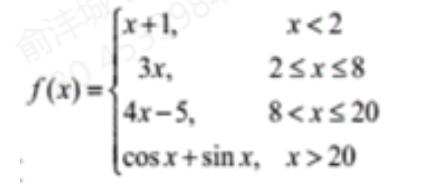

x = [0.1,1,9,22,2*pi];
y = f(x)

**5.**

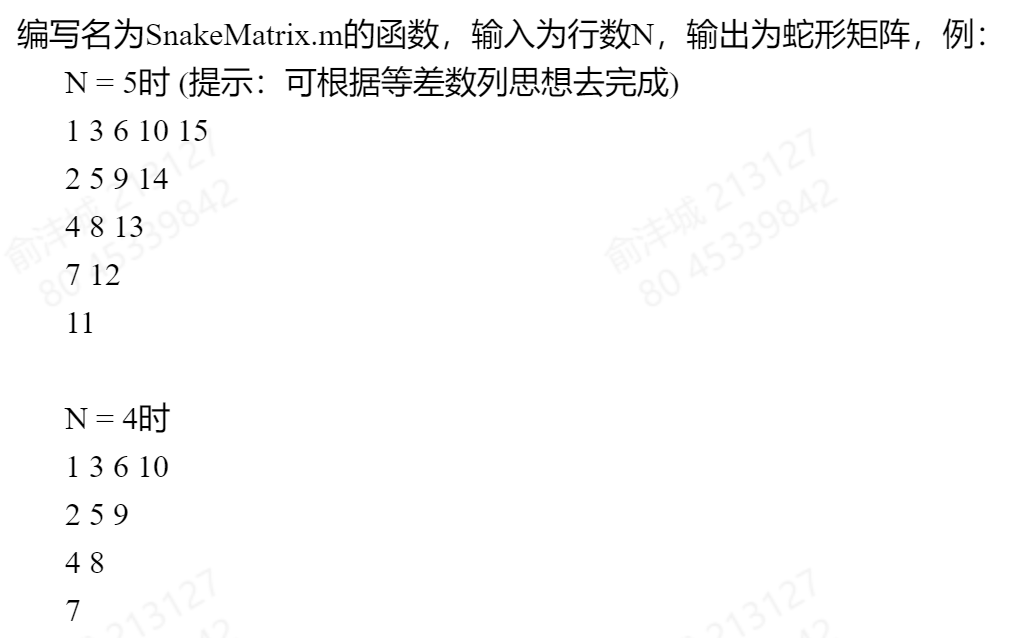

n = 4;
ret = SnakeMatrix(n);
ret

**6.** 一球从100米的高度落下，每次落地后反弹到原来高度的一半再落下。试用MATLAB设计函数Height(x)并引用（x代表第几次落地），分别求解第3，6，10次落地时小球所经过的路程

clc;clear;
x = [1,2,3,4,6,10]; % 落地次数
start_height = 100; % 初始高度
ret = [];
for i = 1:length(x)
    ret = [ret,Height(start_height,x(i))];
end
ret

ret =   100.0000  200.0000  250.0000  275.0000  293.7500  299.6094


**7. **编写函数，实现对于对输入的字符串进行加解密，并输出。

加密方法为：当内容是英文字母时则用该英文字母的后一个字母替换，同时字母变换大小写,如字母a时则替换为B；字母Z时则替换为a；当内容是数字时则把该数字加1，如0替换1，1替换2，9替换0；其他字符不做变化。

例：输入为abcdefg   输出为BCDEFGH

str = 'abcdefgZ809';
code = str2code(str);
disp(code);

BCDEFGHa910


**8. **编写一个函数cal(x)分别计算出当x=1,3,4,7,9的时候，y = x2cos(x)的值

x = [1,3,4,7,9];
y = cal(x);
y

y =     0.5403   -8.9099  -10.4583   36.9412  -73.8016


function tem_c = FCconvert(tem_f)
    tem_c = (5/9)*(tem_f-32);
end
function res = Find7(arr)
    res = [];
    for i = 1:length(arr)
        str = num2str(arr(i));
        if(mod(arr(i),7)==0)
            res = [res,arr(i)];
        elseif(ismember('7',str))
            res = [res,arr(i)];
        end
    end
end
function res = number_guess(num)
    iterators_max = 7;
    for i = 1:iterators_max
        guess = input("请输入一个整数：");
        if(guess == num)
            res = 'You win the game';
            return;
        elseif(guess < num)
            disp('Lower than the answer');
        elseif(guess > num)
            disp('Higher than the answer');
        end
    end
    res = 'GAME OVER';
end
function y = f(x)
    for i = 1:length(x)
        if(x(i)<2)
            y(i) = x(i)+1
        elseif(x(i)>=2&&x(i)<=8)
            y(i) = 3*x(i);
        elseif(x(i)>8&&x(i)<=20)
            y(i) = 4*x(i)-5;
        else
            y(i) = cos(x(i))+sin(x(i));
        end
    end
%     disp("y");
%     disp(y);
end
function ret = SnakeMatrix(n)
    ret = {};
    start_num = 1;
    start_diff = 2;
    col_diff = 1;
    while(n>=0)
        path = [];
        cur_diff = start_diff;
        cur_start_num = start_num;
        % 现在要从start_num开始，连续往path里面push一个值
        % 一共需要push n个值
        for i = 1:n
            path = [path,cur_start_num];
            cur_start_num = cur_start_num +cur_diff;
            cur_diff = cur_diff+1;
        end
        ret = [ret;path];
        n = n-1;
        start_num = start_num + col_diff;
        col_diff = col_diff + 1;
        start_diff = start_diff + 1;
    end
end
function sum = Height(start_height,x)
    % 计算第n次落地的所走的总路程
    startHeight = start_height;
    sum = startHeight;
    times = 1; % 默认已经走了落地一次了
    while(times < x)
        sum = sum + startHeight;
        startHeight = startHeight/2;
        times = times+1;
    end
end
function code = str2code(str)
    code = '';
    for i = 1:length(str)
        if(isletter(str(i)))
            if(str(i)>='a'&&str(i)<='z')
                newch = upper(str(i));
                if (newch=='Z')
                    code(i) = 'A';
                else
                    newch = newch+1;
                    code(i) = newch; 
                end
            end
            if(str(i)>='A'&&str(i)<='Z')
                newch = lower(str(i));
                if (newch=='z')
                    code(i) = 'a';
                else
                    newch = newch+1;
                    code(i) = newch; 
                end
            end
        elseif(str(i)>='0'&&str(i)<'9')
            num = str2num(str(i));
            num = num+1;
            code(i) = num2str(num);
        elseif(str(i)=='9')
            code(i) = '0';
        end
    end
end
function y = cal(x)
    % 数学函数计算函数
    y = [];
    for i = 1:length(x)
        y(i) = (x(i)^2)*cos(x(i));
    end
end